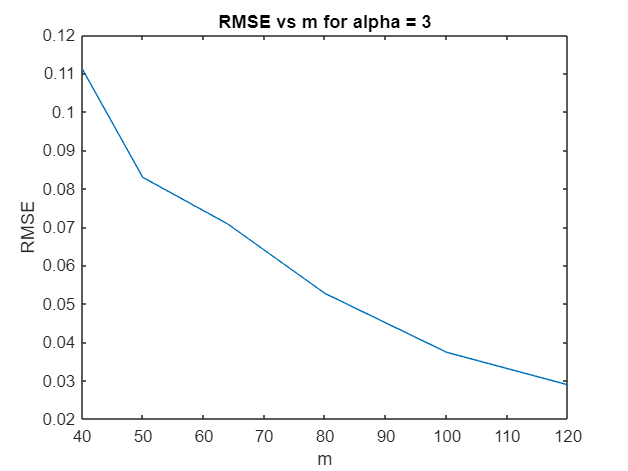

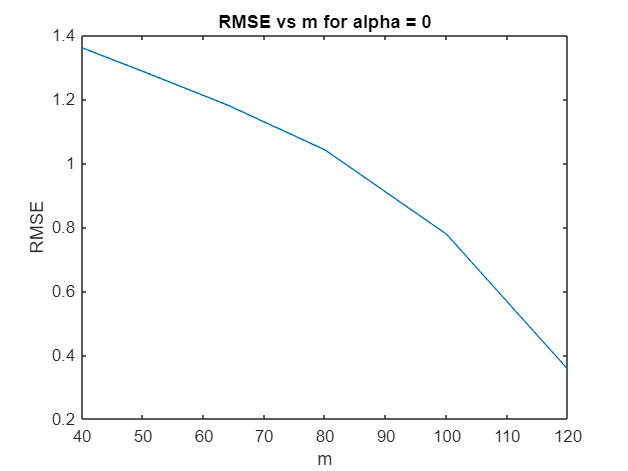

U = RandOrthMat(128);
lamb = zeros(128,1);
c = 1;
alphas = [3.0,0.0];
for k=1:2
    alpha = alphas(k);
    for i=1:128
        lamb(i) = c*i^(-alpha);
    end
    lm = diag(lamb);
    sig = U'*lm*U;
    siginv = pinv(sig);
    mu = double(zeros(128,1));
    X = (mvnrnd(mu, sig,10))';
    M = [40, 50, 64, 80, 100, 120];
    avg_rmses = double(zeros(1,6));

    for i=1:6
        m = M(i);
        avg_rmse = 0.0;
        for j=1:10
            x = X(:,j);
            phi = normrnd(0,sqrt(1/m),m,128);
            y1 = phi*x;
            sig1 = 0.01*sum(abs(y1),1)/m;
            y = y1 + normrnd(0,sig1,m,1);
            x_recon = pinv(phi'*phi+sig1^2*(siginv))*(phi'*y);
            avg_rmse = avg_rmse + norm(x-x_recon)/norm(x);
        end
        avg_rmses(i) = avg_rmse/6.0;
    end
    plot(M,avg_rmses);
    xlabel("m");
    ylabel("RMSE")
    title("RMSE vs m for alpha = "+alpha);
    figure;
end